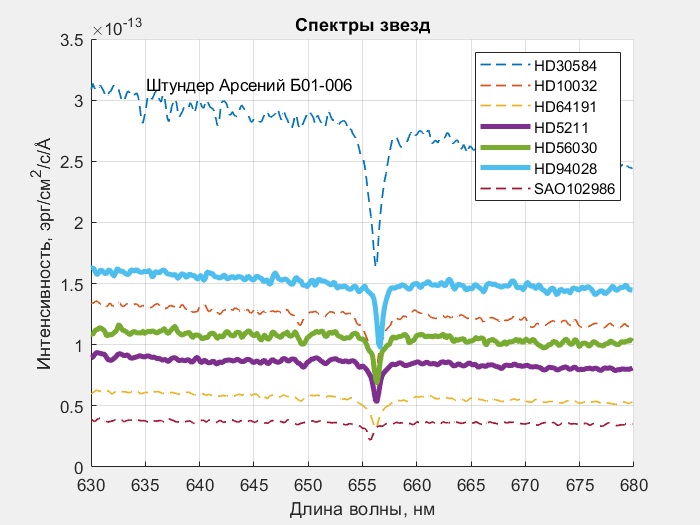

% Данные из файлов
spectra = importdata("spectra.csv");
starNames = importdata("star_names.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");

% Число наблюдений и количество звезд
lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c
nObs = size(spectra, 1);
nStars = size(spectra, 2);

% Диапазон длин волн
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

% Скорость движения звезд
s1 = spectra(:, 1);
[sHa1, idx1] = min(s1);
s2 = spectra(:, 2);
[sHa2, idx2] = min(s2);
s3 = spectra(:, 3);
[sHa3, idx3] = min(s3);
s4 = spectra(:, 4);
[sHa4, idx4] = min(s4);
s5 = spectra(:, 5);
[sHa5, idx5] = min(s5);
s6 = spectra(:, 6);
[sHa6, idx6] = min(s6);
s7 = spectra(:, 7);
[sHa7, idx7] = min(s7);

sn1 = [s1, s2, s3];
sp = [s4, s5, s6];
sn2 = [s7];

lambdaHa1 = lambda(idx1);
lambdaHa2 = lambda(idx2);
lambdaHa3 = lambda(idx3);
lambdaHa4 = lambda(idx4);
lambdaHa5 = lambda(idx5);
lambdaHa6 = lambda(idx6);
lambdaHa7 = lambda(idx7);

z1 = lambdaHa1 / lambdaPr - 1;
z2 = lambdaHa2 / lambdaPr - 1;
z3 = lambdaHa3 / lambdaPr - 1;
z4 = lambdaHa4 / lambdaPr - 1;
z5 = lambdaHa5 / lambdaPr - 1;
z6 = lambdaHa6 / lambdaPr - 1;
z7 = lambdaHa7 / lambdaPr - 1;

speed = [z1, z2, z3, z4, z5, z6, z7]' * speedOfLight;
movaway = [starNames(4), starNames(5), starNames(6)]';

% График со спектрами всех звезд
fg1 = figure;
set(fg1, 'Visible', 'on');
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
title('Спектры звезд')
grid on
hold on

for i = sn1
plot(lambda, i, '--', 'LineWidth', 1)
end

for i = sp
plot(lambda, i, 'LineWidth', 3)
end

for i = sn2
plot(lambda, s7, '--', 'LineWidth', 1)
end

text(lambdaStart+5, max(s1), 'Штундер Арсений Б01-006')

legend('HD30584', 'HD10032', 'HD64191', 'HD5211', 'HD56030', 'HD94028', 'SAO102986')

% Сохраните график
saveas(fg1, 'spectra.png');